# clase 03 abril 2019

clear; clc;
dx=0.1; %incrementos
x1=-2*pi:dx:2*pi;%rango x

aleatorios:

r=8

r = 8

m=randi([-r,r],3,10)

m =      2     4    -8     7     2    -8     3     3    -7     5
     1    -7    -3    -7     3     5    -5     8    -8     3
     3     6    -5     1     6     0     1    -1     2    -3


x=linspace(-1,1,length(m)) %crear un intervalo entre dos valores "-1,1" con el tamaño de la matriz

x =    -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7778    1.0000



plot(x,m');grid;axis([-1,1,-r-1,r+1]) %grid="cuadricula", axis="intervalos para mostrar las graficas"
p=sum(m)/3 %suma promedio por columnas

p =     2.0000    1.0000   -5.3333    0.3333    3.6667   -1.0000   -0.3333    3.3333   -4.3333    1.6667


p1=sum(p)/10 %promedio de la suma por columnas

p1 = 0.1000

line([-1,1],[p1,p1],'color',[.5 .2 .3],'linewidth',4) 
line(x,p,'color',[0 0 0],'linewidth',4) %linea con el intervalo creado "x" y los promedios punto a punto "p"
texto=['prom= ' num2str(p1)] %insertar un texto 

texto = 'prom= 0.1'

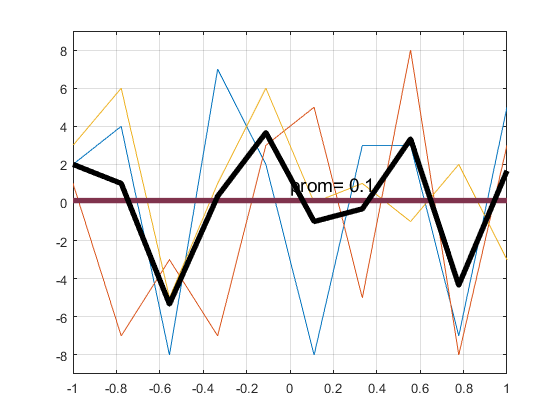

text(0,p1+.8,texto,'fontsize',14) % ubicación del texto con el parametro de tamaño de la fuente

funcion(es)

y1=sinc(x1+pi/3); 
plot(x1,y1,"linewidth",2)
grid; axis([-9,9,-.3,1.2])
[m,x1m]=max(y1) %maximo de la función y su ubicación dentro del arreglo de y1 es decir el valor maximo esta ubicado en la posicion 53 del arreglo

m = 0.9979

x1m = 53

[miny1,x1min]=min(y1) % minimo de la función solo 1 dentro del arreglo de y1

miny1 = -0.2172

x1min = 39

x1(x1m)

ans = -1.0832

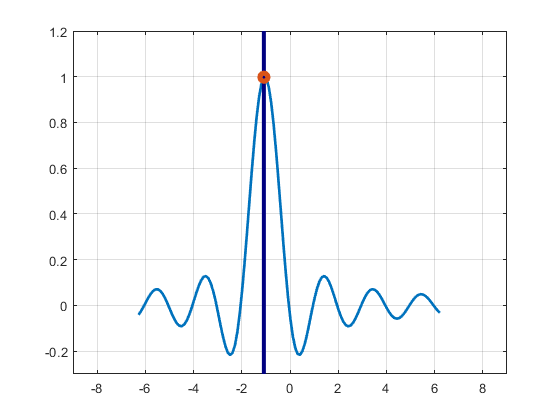

line([x1(x1m),x1(x1m)],[-9,9],"color",[0 0 .5],"linewidth",3)
hold on
plot(x1(x1m),m,"linewidth",4,"marker","o")